% Load in audio .wav files
[x, fs] = audioread('_-_5kbw2Mcw_ 0.000_ 10.000.wav');
t=length(x)
% import audio feature extractor
aFE = audioFeatureExtractor(...
    "SampleRate",fs, ...
    "Window",hamming(round(0.03*fs),"periodic"), ...
    "OverlapLength",round(0.02*fs), ...
    "spectralCentroid",true);
features = extract(aFE,x);
idx = info(aFE)

idx = struct with fields:
    spectralCentroid: 1


Unrecognized function or variable 'chromagram_IF'.

%zero crossing rate
[x, fs] = audioread('_-_5kbw2Mcw_ 0.000_ 10.000.wav');
N = length(x)

N = 220500

t = N/fs

t = 10

zx = find(diff(sign(x)));                                   % Zero-Crossing Indices To 'tx
for k = 1:numel(zx)
    idx_rng = max(zx(k)-1, 1):min(zx(k)+1,numel(t));
    tzro(k) = interp1(x(idx_rng), t(idx_rng), 0);           % Exact Zero Crossings
end

Index exceeds the number of array elements (0).

Error in interp1 (line 153)
        extrapMask = Xq < X(1) | Xq > X(end);

zx_rate = gradient(tzro)

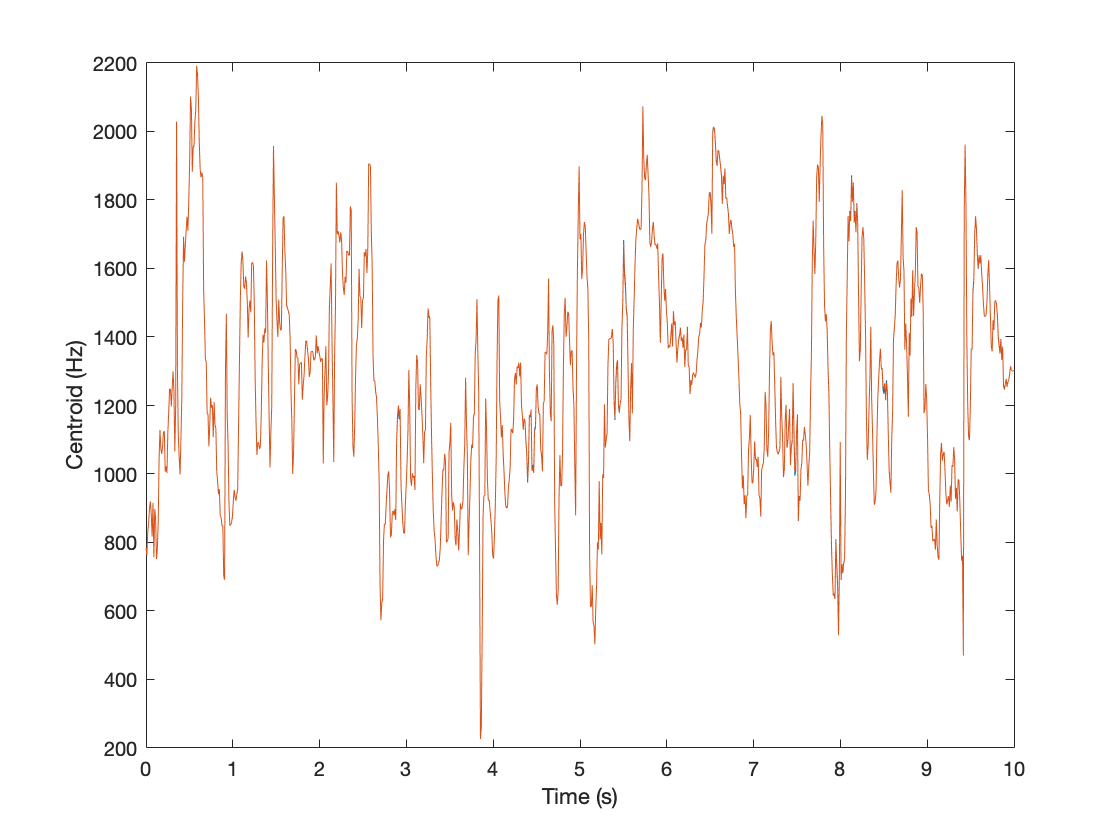

%centroid
centroid = spectralCentroid(x,fs);

t = linspace(0,size(x,1)/fs,size(centroid,1));
plot(t,centroid)
xlabel('Time (s)')1
ylabel('Centroid (Hz)')

average=mean(centroid)

average = 	1.0e+03 *

    1.2754    1.2754


% Load in audio .wav files
[x, fs] = audioread('_-_5kbw2Mcw_ 0.000_ 10.000.wav');

%mfcc
%coeffs = mfcc(x,fs)
[coeffs,delta,deltaDelta,loc] = mfcc(x,fs);
means = mean(coeffs)

means = means(:,:,1) =

    1.4898  -11.7486    4.1950   -2.8032    1.6725   -0.2287   -0.2586    0.0872   -0.6107    0.1930   -0.3669   -0.0004    0.2169   -0.4118


means(:,:,2) =

    1.4900  -11.7485    4.1950   -2.8033    1.6726   -0.2285   -0.2582    0.0866   -0.6105    0.1925   -0.3664   -0.0005    0.2172   -0.4115


%spectrogram
S = melSpectrogram(x,fs);

[numBands,numFrames] = size(S);
fprintf("Number of bandpass filters in filterbank: %d\n",numBands)

Number of bandpass filters in filterbank: 32



fprintf("Number of frames in spectrogram: %d\n",numFrames)

Number of frames in spectrogram: 1990


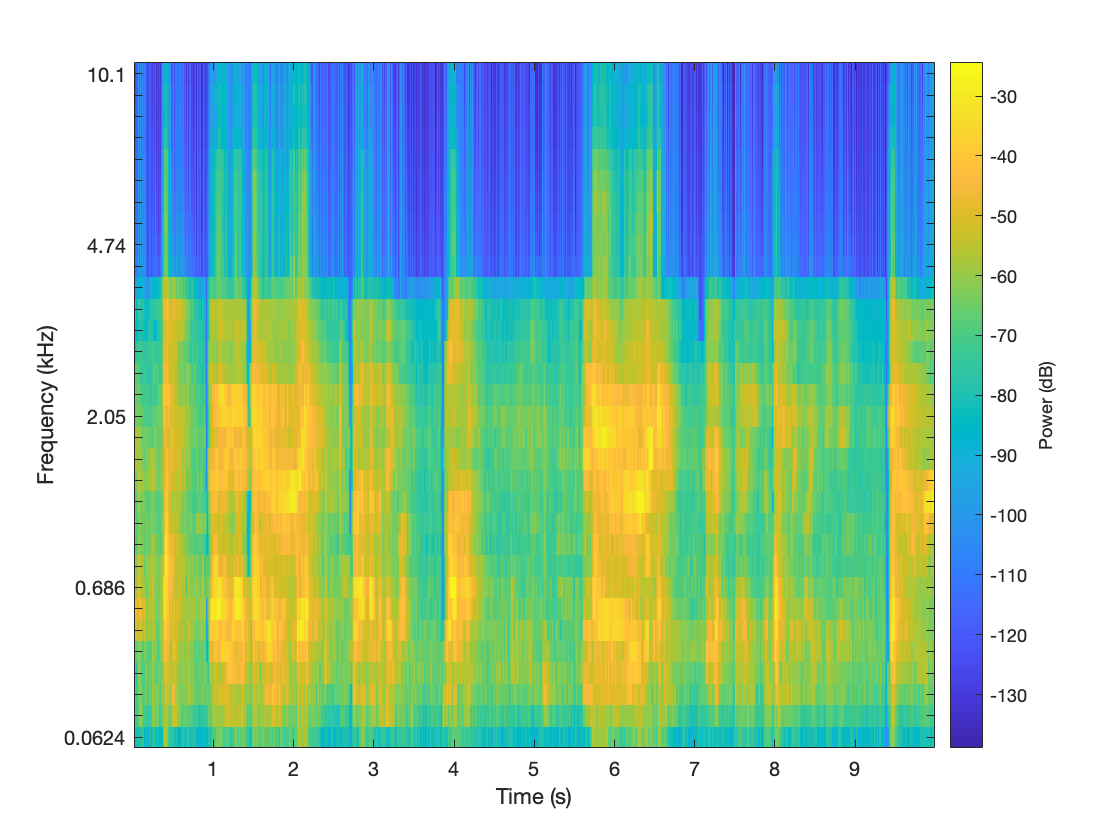

melSpectrogram(x,fs)




[~,~,~,ps] = spectrogram(v,win,...
                  overlapLength,...
                  numel(win),...
                  Fs,...
                  'power',...
                  'onesided');

Unrecognized function or variable 'v'.

vsc = FeatureSpectralCentroid(ps, Fs);
vsc = vsc'; % reorient so that centroid is along rows.
mean((centroid-vsc).^2,'all') % 1.6829e-29 
%aFE = audioFeatureExtractor()
% Use the extractor to create a csv of useful features
    % spectrum stum
    % other usefull things see documentation for what you can get
    
    
    
% m = [234 2;671 5;735 1;264 2;346 7] 
% writematrix(m,'M.csv') 